clearvars

% Read the data into a table
%data = readtable("C:\Chengming_Li\GitHub\ECE266_CMOSCircuitLab\Lab6_EvalADC\Data\INL_DNL_FromFuncGen.xlsx", 'FileType', 'spreadsheet');
data = readtable("C:\Chengming_Li\GitHub\ECE266_CMOSCircuitLab\Lab6_EvalADC\Data\INL_DNL_FromTI.xlsx", 'FileType', 'spreadsheet');

% Extract the desired columns
% codes = data{:, 'Codes - Histogram'};   % Codes - Histogram column
% hits = data{:, '#Hits - Histogram'};    % #Hits - Histogram column
codes = data(:,1);
codes = table2array(codes);
hits = data(:,2);
hits = table2array(hits);
ADC_bits = 16;
VFS = 5;
Amp = VFS/2;
total_sampels = 1048576;

## Fake Sine data

## DNL

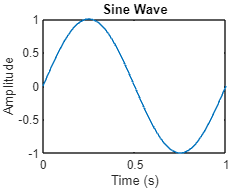

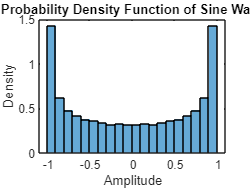

DNL = zeros(length(codes),1);

p =zeros(length(codes),1);
hits_prob = zeros(length(codes),1);
hits_sum = sum(hits);
ideal_hits = hits_sum/(2^16)
for i = 1:length(codes)
    p = calc_Prob(VFS, codes(i,1), ADC_bits, Amp) ; 
    DNL(i) = ( hits(i,1) / (hits_sum*p) ) - 1; 

ideal_hits = 4


    % display(p);
    % display(DNL(i));
    % display(p);
    % display(p_n_norm);
end
DNL_sum = sum(DNL)
figure
plot(codes,DNL,'b--',"DisplayName","DNL")
xlabel("Code")

DNL_sum = 1.0424e+04

ylabel("DNL")
ylim([-1,3])
% xlim([0 7e4])
% ylim-()
title("Differential Non-Linearity (DNL) with Missing Codes")
legend;
grid on


## INL

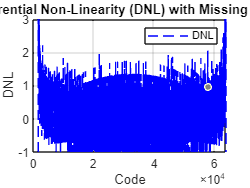

INL = zeros(length(codes),1);



for i = 1:length(hits)
    INL(i) = sum(DNL(1:i,1));
end

figure
plot(INL(:,1),codes(:,1),'k--',"DisplayName","INL")
xlabel("Code")
ylabel("INL")
title("Integrated Non-Linearity (INL) with Missing Codes")
legend;


## Function DNL Probaility

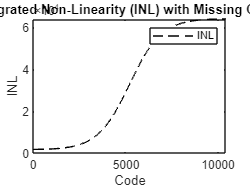

function p = calc_Prob(VFS, n, bits, amp)
     % VFS: Full scale of ADC input
     % n: is the code
     % bits: number of bits of the ADC

     % amp: amplitude
     asin_part1 = asin((VFS*(n - 2^(bits-1))) / (amp * 2^bits));
     asin_part2 = asin((VFS*(n-1-2^(bits-1))) / (amp * 2^bits));
     p = 1/pi * (asin_part1 - asin_part2);
end